# LeRoy Raw Data

**Author:** Scott Campit

## Summary

This livescript computes correlations between CCLE datasets.

## Load data and get intersection between transcriptomics and LeRoy dataset

clear all;

% First we need to clean up the metabolomics dataset
metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'all');

metabolomics_ccl = extractBefore(string(table2cell(metabolomics(:, 'CCLE_ID'))), '_');
metabolomics(:, 'CCLE_ID') = cellstr(metabolomics_ccl);

% Next, we need to map between datasets
leroy = readtable('LeRoy_et_al.xlsx', 'sheet', 'Single');

[~, ia, ib] = intersect(string(table2cell(metabolomics(:, 'CCLE_ID'))), ...
                        string(table2cell(leroy(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
leroy = leroy(ib, :);

Out of the 12 cancer cell lines that intersect between the LeRoy dataset and the metabolomics dataset, only 6 had intersecting medium. I will use those to compute correlations.

- HL60

- HUH7

- MCF7

- NB4

- SW480

- U937

%cellLines2Keep = [          ...
%    "HL60", "HUH7", "MCF7", ...
%    "NB4", "SW480", "U937"  ...
%];

% Get intersection between filtered datasets 
%[~, idx] = intersect(table2array(leroy(:, 'CellLine')), cellLines2Keep);
%metabolomics = metabolomics(idx, :);
%leroy = leroy(idx, :);

## Methylation and acetylation subsets

### Histone markers from LeRoy

leroy_methylation = readtable('LeRoy_et_al.xlsx', 'sheet', 'Methylation');

leroy_methylation = leroy_methylation(ib, :);
%leroy_methylation = leroy_methylation(idx, :);

leroy_acetylation = readtable('LeRoy_et_al.xlsx', 'sheet', 'Acetylation');

leroy_acetylation = leroy_acetylation(ib, :);
%leroy_acetylation = leroy_acetylation(idx, :);

### Metabolomics

% Methylation
methylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'Methylation');

methylation_metabolomics = methylation_metabolomics(ia, :);
%methylation_metabolomics = methylation_metabolomics(idx, :);

% Acetylation
acetylation_metabolomics = readtable('CCLE_metabolomics_processed.xlsx', 'sheet', 'Acetylation');

acetylation_metabolomics = acetylation_metabolomics(ia, :);
%acetylation_metabolomics = acetylation_metabolomics(idx, :);

## Correlation between GCP and metabolomics

### Acetylation

#### Pearson correlation coefficient

This module computes the Pearson and Spearman correlation matrix between each GCP and metabolite value pair. Then, it finds significant interactions. These can be plotted either in-line or through another programming language.

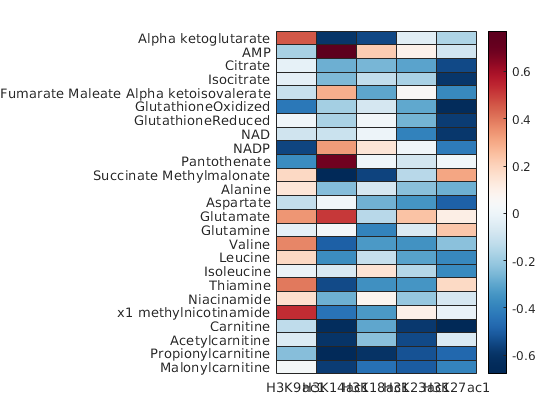

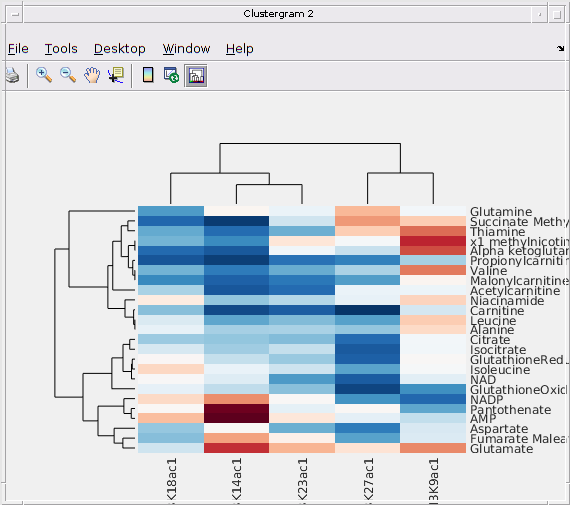

Clustergram object with 25 rows of nodes and 5 columns of nodes.



% Compute pearson correlation coefficient matrix
cellLines2Keep = [          ...
    "HL60", "HUH7", "MCF7", ...
    "NB4", "SW480", "U937"  ...
];

% Get intersection between filtered datasets 
[~, idx] = intersect(table2array(leroy_acetylation(:, 'CellLine')), cellLines2Keep);
acetylation_metabolomics = acetylation_metabolomics(idx, :);
leroy_acetylation = leroy_acetylation(idx, :);

[pearsonmat, pearsonpval] = corr(table2array(leroy_acetylation(:, 2:end)), ...
                                 table2array(acetylation_metabolomics(:, 3:end)), ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
acetylmetabolites = strrep(acetylation_metabolomics.Properties.VariableNames(:, 3:end), '_', ' ');
acetylmarks = leroy_acetylation.Properties.VariableNames(:, 2:end);

heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', acetylmetabolites, ...
        'XData', acetylmarks)
% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', acetylmetabolites', ...
            'ColumnLabels', acetylmarks, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

### Applying a mask

Next, I decided to look at these matrices using the p-value mask. Because there are NaNs, we can't make a clustergram for this set. 

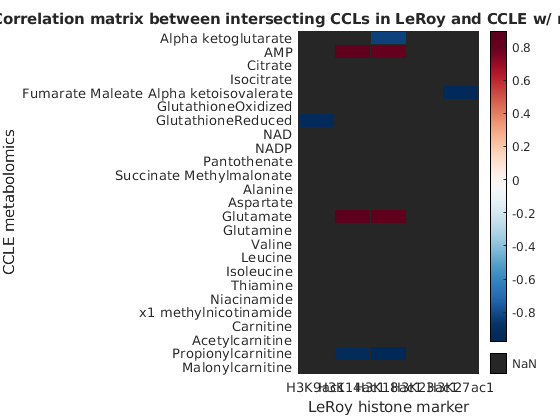

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;


% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', acetylmetabolites, ...
        'XData', acetylmarks)
xlabel('LeRoy histone marker');
ylabel('CCLE metabolomics');
title('Correlation matrix between intersecting CCLs in LeRoy and CCLE w/ matching media (n=6 CCLs)')

#### Methylation

Of course, because we're showing all the histone markers and all metabolites, this is pretty terrible to analyze. Let's start simplifying by removing histone markers I'm not interested in analyzing.

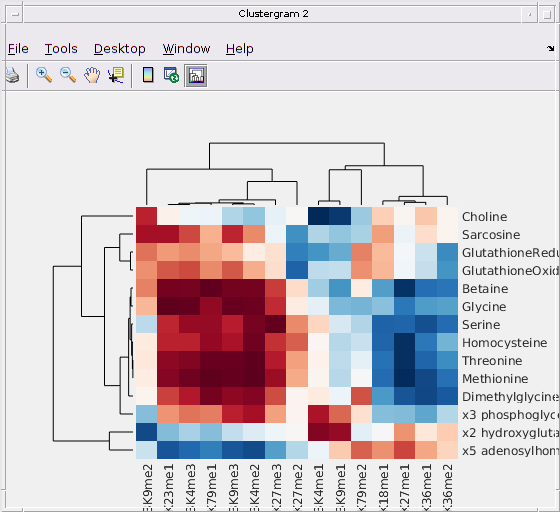

Clustergram object with 14 rows of nodes and 15 columns of nodes.



% Get intersection between filtered datasets 
[~, idx] = intersect(table2array(leroy_methylation(:, 'CellLine')), cellLines2Keep);
methylation_metabolomics = methylation_metabolomics(idx, :);
leroy_methylation = leroy_methylation(idx, :);

[pearsonmat, pearsonpval] = corr(table2array(leroy_methylation(:, 2:end)), ...
                                 table2array(methylation_metabolomics(:, 3:end)), ...
                                 'Type', 'Pearson');
                             
methylmetabolites = strrep(methylation_metabolomics.Properties.VariableNames(:, 3:end), '_', ' ');
methylmarks = leroy_methylation.Properties.VariableNames(:, 2:end);
                             
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', methylmetabolites, ...
        'XData', methylmarks)
xlabel('LeRoy markers');
ylabel('CCLE metabolomics');
title('Correlation matrix between intersecting CCLs in LeRoy and CCLE w/ matching media (n=6 CCLs)')

clustergram(pearsonmat', ...
            'RowLabels', methylmetabolites, ...

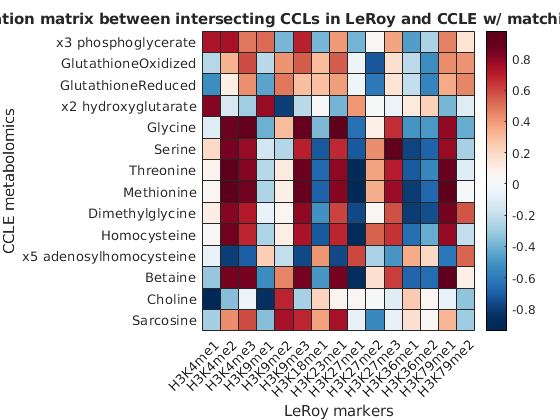

            'ColumnLabels', methylmarks, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...

            'Colormap', redbluecmap)
xlabel('LeRoy markers');
ylabel('CCLE metabolomics');
title('Correlation matrix between intersecting CCLs in LeRoy and CCLE w/ matching media (n=6 CCLs)')

#### Mask

Add a p-value mask to this metabolic subset.

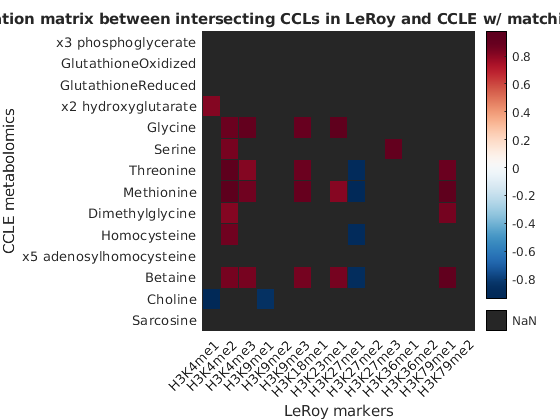

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', methylmetabolites, ...
        'XData', methylmarks)
xlabel('LeRoy markers');
ylabel('CCLE metabolomics');

title('Correlation matrix between intersecting CCLs in LeRoy and CCLE w/ matching media (n=6 CCLs)')